clearvars; close all;
syms x y xr yr xo yo x0 y0 m
syms d h positive

%Senza perdita di generalitá impongo che il robot si trovi nell'origine
xr = 0; yr = 0;

%1° condizione:impongo che la circonferenza sia tangente alla direzione del robot
x0 = -m*y0;
%Impongo che la circonferenza di raggio d centrata in Omega passi dal robot
d = sqrt((xr-x0)^2 + (yr-y0)^2);
%2° condizione:impongo che la circo in Omega sia tangente alla circo in obst
eq = (x0-xo)^2 + (y0-yo)^2 == (d+h)^2;
sol = solve(eq,y0);

m = tan(1.2); xr = 5; yr = 0; xo0 = 6; yo0 = 2; h = 0.8; xg = 8; yg = 5;
xo = xo0 - xr; yo = yo0 - yr;
yOmega = double(subs(sol));
xOmega = double(-m*yOmega);
dOmega = double(sqrt(xOmega.^2 + yOmega.^2));

Plotting

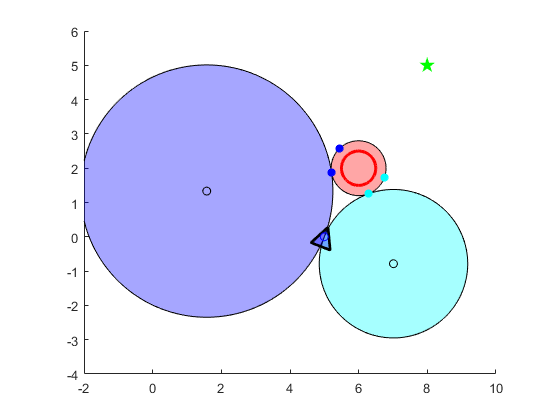

yOmega = yOmega + yr; xOmega = xOmega + xr; xo = xo0; yo = yo0;
figure; axis equal; axis([-2 10 -4 6]); hold on;
omega1 = nsidedpoly(2000, 'Center', [xOmega(1) yOmega(1)], 'Radius', double(dOmega(1)));
omega2 = nsidedpoly(2000, 'Center', [xOmega(2) yOmega(2)], 'Radius', double(dOmega(2)));
plot(omega1, 'FaceColor', 'b'); plot(xOmega(1),yOmega(1),"ok");
plot(omega2, 'FaceColor', 'c'); plot(xOmega(2),yOmega(2),"ok");
obst = nsidedpoly(2000, 'Center', [xo yo], 'Radius', double(h));
plot(obst, 'FaceColor', 'r');
grid = Grid(100,10); r = Robot(0.6,0.6,grid); r.draw();
o = Obstacle(xo,yo,[0,0]); o.draw(); load xp2yp2;
for i = 1 : 2
    centerDir = [xo yo]-[xOmega(i) yOmega(i)];
    centerDir = centerDir/norm(centerDir);
    P1 = [xOmega(i) yOmega(i)] + dOmega(i).*centerDir;
    if i == 1
        plot(P1(1),P1(2),"*b","LineWidth",2);
    else
        plot(P1(1),P1(2),"*c","LineWidth",2)
    end
    P2 = double(subs(solxp2(i)));
    syms xp2; xp2 = P2(1);
    P2(2) = double(subs(solyp2(i)));
    if i == 1
        plot(P2(1),P2(2),"*b","LineWidth",2);
    else
        plot(P2(1),P2(2),"*c","LineWidth",2)
    end
end
plot(xg,yg,"pg","LineWidth",2);